# Hydrological terrain attributes

TopoToolbox major strength is in calculating hydrological terrain attributes. These terrain attributes are used to determine the paths of water and sediment through the landscapes. Local flow directions stored as FLOWobj are the basis for the derivation of these terrain attributes. 

FLOWobj are derived from the DEM. FLOWobj is the name of the class as well as the constructor function.

DEM = GRIDobj('srtm_bigtujunga30m_utm11.tif');
FD  = FLOWobj(DEM);

Unlike most GIS software, TopoToolbox requires no preprocessing or hydrological conditioning before calling FLOWobj. Don't fill sinks although there is a function available to do this (`fillsinks`). FLOWobj will determine closed depressions and derive flow directions in these sinks so that flow paths run along the valley thalwegs as closely as possible. Filling the DEM before would discard the topographic information in topographic depressions that would otherwise constrain the flow paths.

By default, TopoToolbox calculates single flow directions. Please see the help of FLOWobj for how to calculate multiple flow directions.

## Flow accumulation

Flow accumulation refers to the number of pixels that drain into each pixel. If multiplied by pixel size, flow accumulation equals the drainage or catchment area upstream of each pixel.  The function flowacc calculates flow accumulation and returns a GRIDobj.

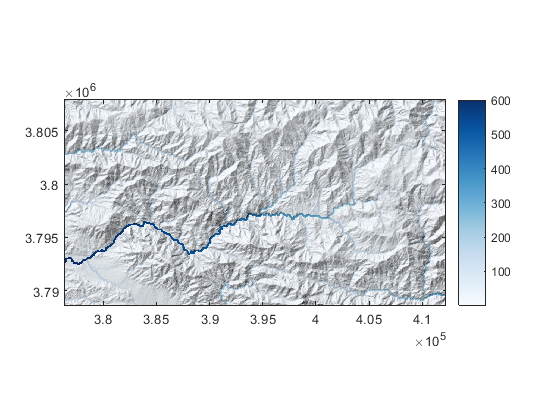

A = flowacc(FD);
imageschs(DEM,dilate(sqrt(A),ones(5)),'colormap','flowcolor')

## Drainage basin delineation

Catchment can be derived using the function drainagebasins. The function returns a GRIDobj with integer values (a label grid).

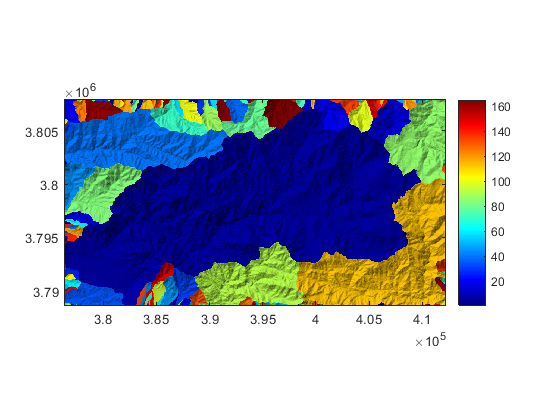

D = drainagebasins(FD);
imageschs(DEM,shufflelabel(D))